# Earthquakes - Exploring

## 1.

Load `quakes14.mat`. This file contains a table of earthquake data for 14 countries through the 20th century. The data includes the date and time of the quake, its magnitude, location, and impact (in terms of life and cost).

load quakes14.mat
quakes

quakes = 1704×12 table
            YEAR    MONTH    DAY    HOUR    MINUTE    MAGNITUDE        COUNTRY         COUNTRYCODE    LATITUDE    LONGITUDE    DEATHS    DAMAGECOST
            ____    _____    ___    ____    ______    _________    ________________    ___________    ________    _________    ______    __________
    2566    1900      1      11       9        7         NaN       JAPAN                   JP           36.5         133.5      NaN         NaN    
    2567    1900      1      14     NaN      NaN         NaN       INDONESIA               

## 2.

Make a histogram of earthquake magnitudes. Calculate the skewness and kurtosis, and compare them to the skewness and kurtosis of a normal distribution (0 and 3, respectively).

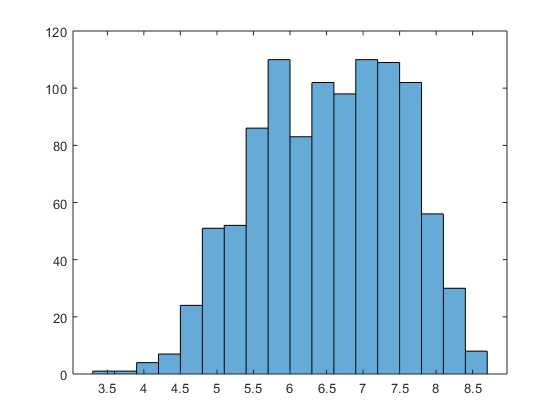

histogram(quakes.MAGNITUDE)

skew = skewness(quakes.MAGNITUDE) 

skew = -0.1924

% <0 => left-tailed
kurt = kurtosis(quakes.MAGNITUDE)

kurt = 2.2865

% <3 => "rounder" than normal distribution

## 3.

Repeat step 2 with just Japanese earthquakes.

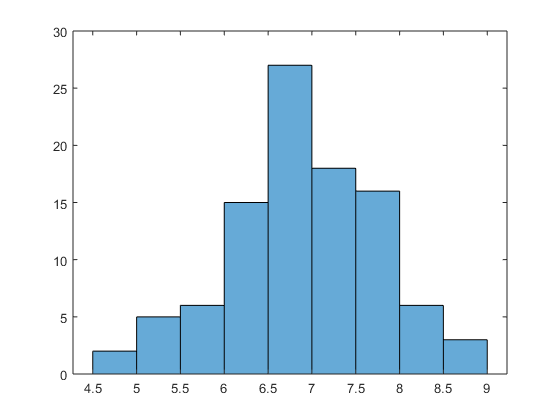

japQu = quakes(quakes.COUNTRY == 'JAPAN',:);
% use logical indexing to extract japanese quakes

histogram(japQu.MAGNITUDE)

jap_skew = skewness(japQu.MAGNITUDE) 

jap_skew = -0.1859

% <0 => left-tailed, nearly the same as all
jap_kurt = kurtosis(japQu.MAGNITUDE)

jap_kurt = 2.7830

% <3 => "rounder" than normal distribution, but a little peakier than all

## 4.

Use `grpstats` to calculate the mean magnitude for each country.

mbc = grpstats(quakes.MAGNITUDE,quakes.COUNTRY)

mbc =     7.1773
    6.1584
    6.2724
    6.8178
    5.9622
    5.7806
    6.8459
    7.2520
    7.2880
    6.7472


% compare this to:
mean_by_ctry = grpstats(quakes,'COUNTRY',{@mean,@median},'DataVars','MAGNITUDE')

mean_by_ctry = 14×4 table
                            COUNTRY         GroupCount    mean_MAGNITUDE    median_MAGNITUDE
                        ________________    __________    ______________    ________________
    CHILE               CHILE                   89            7.1773               7.3      
    CHINA               CHINA                  227            6.1584                 6      
    GREECE              GREECE                  86            6.2724               6.3      
    INDONESIA           INDONESIA              168            6.8178               6.8      
    IRAN                IRAN                   142            5.9622               5.8      
    ITALY               ITALY                  110            5.7806               5.

## 5.

Sort the countries by mean magnitude. **Hint:** Use categories to get the country names.

ctrys = categories(quakes.COUNTRY);
[~,idx] = sort(mbc,'descend');
ctrys_by_meanmag = ctrys(idx)

ctrys_by_meanmag = 14×1 cell array
    {'PAPUA NEW GUINEA'}
    {'MEXICO'          }
    {'CHILE'           }
    {'RUSSIA'          }
    {'PHILIPPINES'     }
    {'JAPAN'           }
    {'INDONESIA'       }
    {'PERU'            }
    {'USA'             }
    {'GREECE'          }
    {'CHINA'           }
    {'TURKEY'          }
    {'IRAN'            }
    {'ITALY'           }

% compare this to:
t = sortrows(mean_by_ctry,'mean_MAGNITUDE','descend');
t.COUNTRY

ans = 14×1 categorical array
     PAPUA NEW GUINEA 
     MEXICO 
     CHILE 
     RUSSIA 
     PHILIPPINES 
     JAPAN 
     INDONESIA 
     PERU 
     USA 
     GREECE 
     CHINA 
     TURKEY 
     IRAN 
     ITALY 

## 6.

Make a boxplot of magnitudes grouped by country. Does this agree with your findings above?

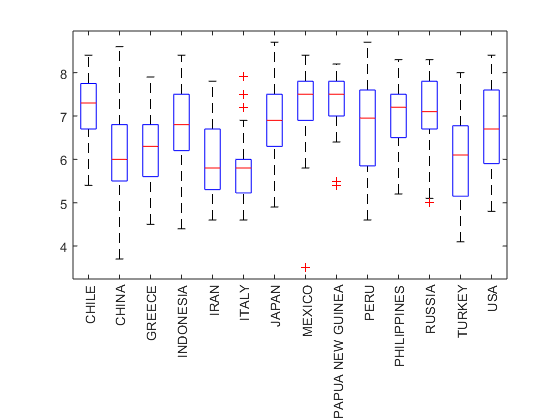

boxplot(quakes.MAGNITUDE,quakes.COUNTRY)
xtickangle(90)

## 7.

Make a scatter plot of the logarithm of the number of deaths and the logarithm of the damage cost. (These variables have a highly exponential distribution; taking the logarithm makes visualization of their relationship clearer.) Calculate the correlation coefficient.

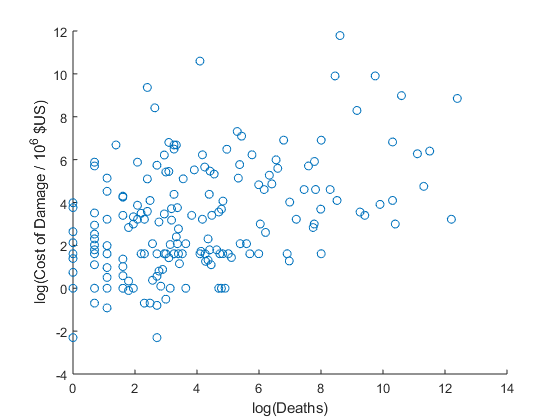

scatter(log(quakes.DEATHS),log(quakes.DAMAGECOST))
xlabel('log(Deaths)'), ylabel('log(Cost of Damage / 10^6 $US)')

corr(log(quakes.DEATHS),log(quakes.DAMAGECOST),'rows','complete')

ans = 0.4584